# 3.4. Цепи с индуктивно связанными катушками

clear

Потокосцепление [самоиндукции](https://ru.wikipedia.org/wiki/%D0%A1%D0%B0%D0%BC%D0%BE%D0%B8%D0%BD%D0%B4%D1%83%D0%BA%D1%86%D0%B8%D1%8F)

syms Psi_L1 w1 Phi
Psi_L1==w1*Phi                          % (3.36)

$$ans = \Psi_{\mathrm{L1}}=\Phi \,w_{1}$$

% где
% w1 - число витков первой катушки
% Phi - магнитный поток, проходящий через один виток катушки

ЭДС самоиндукции

syms e_L t Psi_L(t)
e_L==-diff(Psi_L)                   % (3.37)

$$ans(t) = e_{L}=-\frac{\partial }{\partial t}\Psi_{L}\left(t\right)$$

ЭДС [взаимной индукции](https://ru.wikipedia.org/wiki/%D0%92%D0%B7%D0%B0%D0%B8%D0%BC%D0%BE%D0%B8%D0%BD%D0%B4%D1%83%D0%BA%D1%86%D0%B8%D1%8F)

syms e_M t Psi_M(t) M i(t)
e_M==-diff(Psi_M), e_M==-M*diff(i)         % (3.38)

$$ans(t) = e_{M}=-\frac{\partial }{\partial t}\Psi_{M}\left(t\right)$$

$$ans(t) = e_{M}=-M\,\frac{\partial }{\partial t}i\left(t\right)$$

clear
% Напряжения u1, u2 каждой индуктивно связанной катушки
syms u1 u_L1 u_M12 t Psi_L1(t) Psi_M12(t) L1 M i1(t) i2(t)

Согласное включение катушек

u1==u_L1+u_M12, u1==diff(Psi_L1)+diff(Psi_M12), u1==L1*diff(i1)+M*diff(i2)   % (3.39)

$$ans = u_{1}=u_{\mathrm{L1}}+u_{\mathrm{M12}}$$

$$ans(t) = u_{1}=\frac{\partial }{\partial t}\Psi_{\mathrm{L1}}\left(t\right)+\frac{\partial }{\partial t}\Psi_{\mathrm{M12}}\left(t\right)$$

$$ans(t) = u_{1}=L_{1}\,\frac{\partial }{\partial t}i_{1}\left(t\right)+M\,\frac{\partial }{\partial t}i_{2}\left(t\right)$$

Встречное включение катушек

u1==u_L1-u_M12, u1==diff(Psi_L1)-diff(Psi_M12), u1==L1*diff(i1)-M*diff(i2)

$$ans = u_{1}=u_{\mathrm{L1}}-u_{\mathrm{M12}}$$

$$ans(t) = u_{1}=\frac{\partial }{\partial t}\Psi_{\mathrm{L1}}\left(t\right)-\frac{\partial }{\partial t}\Psi_{\mathrm{M12}}\left(t\right)$$

$$ans(t) = u_{1}=L_{1}\,\frac{\partial }{\partial t}i_{1}\left(t\right)-M\,\frac{\partial }{\partial t}i_{2}\left(t\right)$$

syms u2 u_L2 u_M21 t Psi_L2(t) Psi_M21(t) L2 M i1(t) i2(t)
% Согласное включение катушек
u2==u_L2+u_M21, u2==diff(Psi_L2)+diff(Psi_M21), u2==L2*diff(i2)+M*diff(i1)

$$ans = u_{2}=u_{\mathrm{L2}}+u_{\mathrm{M21}}$$

$$ans(t) = u_{2}=\frac{\partial }{\partial t}\Psi_{\mathrm{L2}}\left(t\right)+\frac{\partial }{\partial t}\Psi_{\mathrm{M21}}\left(t\right)$$

$$ans(t) = u_{2}=L_{2}\,\frac{\partial }{\partial t}i_{2}\left(t\right)+M\,\frac{\partial }{\partial t}i_{1}\left(t\right)$$

% Встречное включение катушек
u2==u_L2-u_M21, u2==diff(Psi_L2)-diff(Psi_M21), u2==L2*diff(i2)-M*diff(i1)

$$ans = u_{2}=u_{\mathrm{L2}}-u_{\mathrm{M21}}$$

$$ans(t) = u_{2}=\frac{\partial }{\partial t}\Psi_{\mathrm{L2}}\left(t\right)-\frac{\partial }{\partial t}\Psi_{\mathrm{M21}}\left(t\right)$$

$$ans(t) = u_{2}=L_{2}\,\frac{\partial }{\partial t}i_{2}\left(t\right)-M\,\frac{\partial }{\partial t}i_{1}\left(t\right)$$

clear

Комплексная форма записи

syms U1 U2 omega L1 L2 M I1 I2
U1==1j*omega*L1*I1+1j*omega*M*I2               % (3.40)

$$ans = U_{1}=I_{1}\,L_{1}\,\omega \,\mathrm{i}+I_{2}\,M\,\omega \,\mathrm{i}$$

U2==1j*omega*L2*I2+1j*omega*M*I1

$$ans = U_{2}=I_{2}\,L_{2}\,\omega \,\mathrm{i}+I_{1}\,M\,\omega \,\mathrm{i}$$

U1==1j*omega*L1*I1-1j*omega*M*I2

$$ans = U_{1}=I_{1}\,L_{1}\,\omega \,\mathrm{i}-I_{2}\,M\,\omega \,\mathrm{i}$$

U2==1j*omega*L2*I2-1j*omega*M*I1

$$ans = U_{2}=I_{2}\,L_{2}\,\omega \,\mathrm{i}-I_{1}\,M\,\omega \,\mathrm{i}$$

Эквивалентное сопротивление при последовательном соединиении двух индутивно связанных катушек

syms R1 R2 x1 x2 x_M R_E
R_E==R1+1j*x1+R2+1j*x2+2*1j*x_M                % (3.41)

$$ans = R_{E}=R_{1}+R_{2}+x_{1}\,\mathrm{i}+x_{2}\,\mathrm{i}+2\,x_{M}\,\mathrm{i}$$

R_E==R1+1j*x1+R2+1j*x2-2*1j*x_M

$$ans = R_{E}=R_{1}+R_{2}+x_{1}\,\mathrm{i}+x_{2}\,\mathrm{i}-2\,x_{M}\,\mathrm{i}$$

% где
% x_M=omega*M - сопротивление вазимной индукции

Коэффициент магнитной связи

syms K M L1 L2
K==M/sqrt(L1*L2), K<1           % (3.42)

$$ans = K=\frac{M}{\sqrt{L_{1}\,L_{2}}}$$

$$ans = K<1$$

#### Цепь с параллельным соединением индуктивно связанных катушек

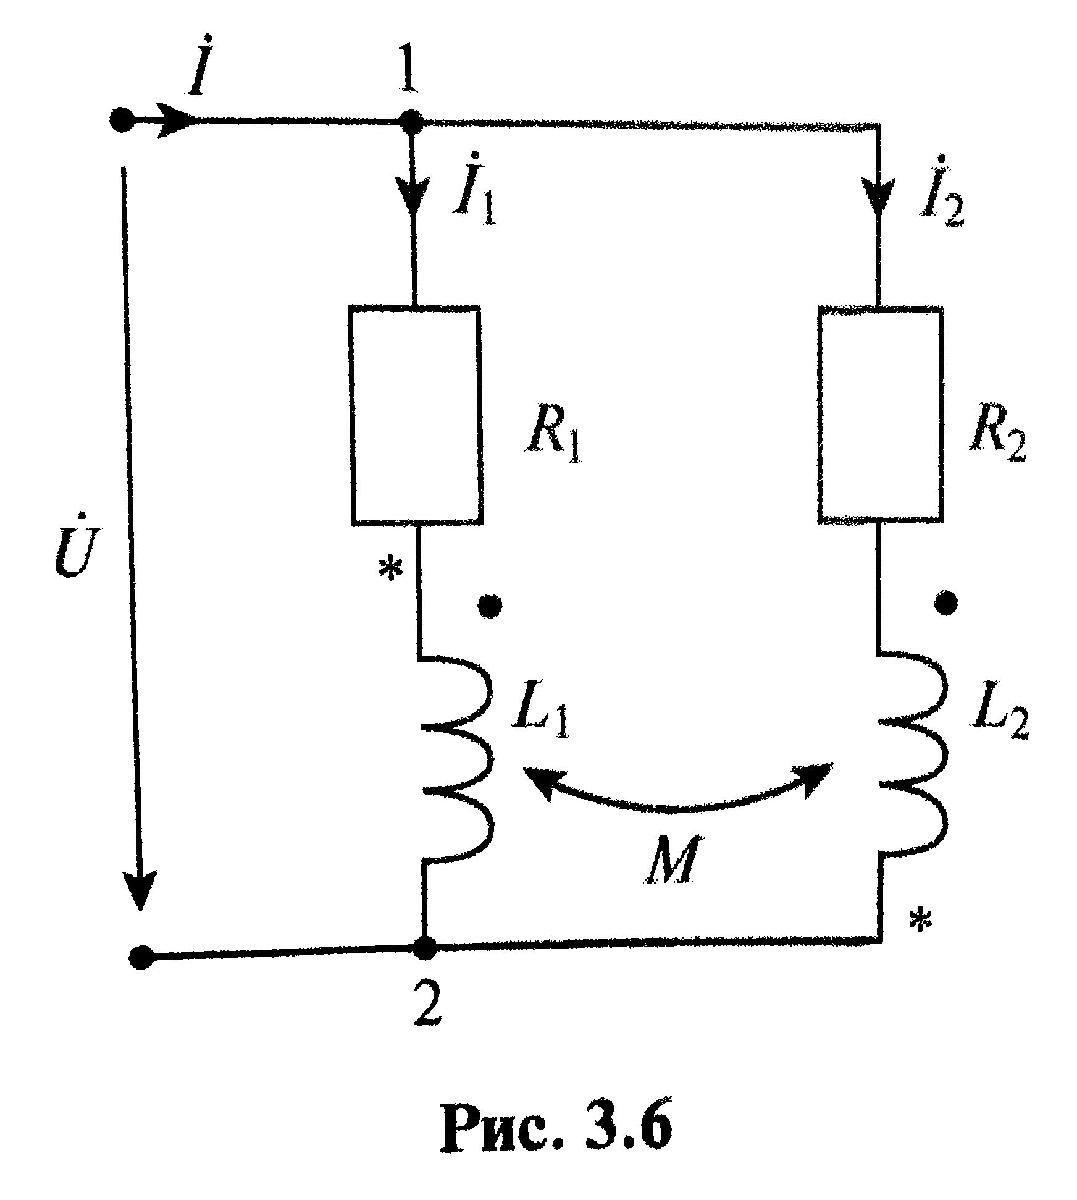

syms U R1 R2 L1 L2 M Z1 Z2 Z_M I1 I2 omega
eq1=U==Z1*I1+Z_M*I2, eq2=U==Z_M*I1+Z2*I2                 % (3.43)

$$eq1 = U=I_{1}\,Z_{1}+I_{2}\,Z_{M}$$

$$eq2 = U=I_{2}\,Z_{2}+I_{1}\,Z_{M}$$

eq3=U==Z1*I1-Z_M*I2, eq4=U==-Z_M*I1+Z2*I2

$$eq3 = U=I_{1}\,Z_{1}-I_{2}\,Z_{M}$$

$$eq4 = U=I_{2}\,Z_{2}-I_{1}\,Z_{M}$$

% где
Z1==R1+1j*omega*L1, Z2==R2+1j*omega*L2, Z_M==1j*omega*M

$$ans = Z_{1}=R_{1}+L_{1}\,\omega \,\mathrm{i}$$

$$ans = Z_{2}=R_{2}+L_{2}\,\omega \,\mathrm{i}$$

$$ans = Z_{M}=M\,\omega \,\mathrm{i}$$

slv=solve(eq1,eq2,[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


I1==slv.I1                       % (3.44)

$$ans = I_{1}=\frac{U\,\left(Z_{2}-Z_{M}\right)}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

I2==slv.I2

$$ans = I_{2}=\frac{U\,\left(Z_{1}-Z_{M}\right)}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

slv=solve(eq3,eq4,[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


I1==slv.I1

$$ans = I_{1}=\frac{U\,\left(Z_{2}+Z_{M}\right)}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

I2==slv.I2

$$ans = I_{2}=\frac{U\,\left(Z_{1}+Z_{M}\right)}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

#### Цепь с трансформаторной связью между катушками

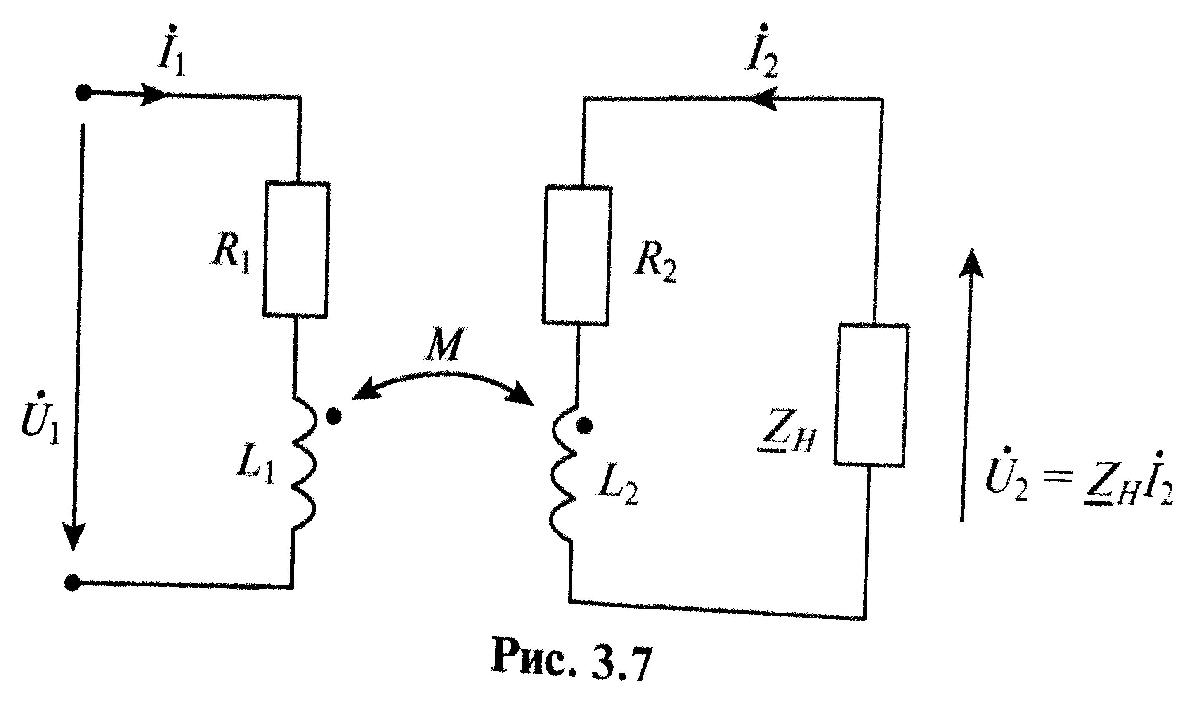

clear
syms U1 R1 R2 Z_N L1 L2 M I1 I2 omega
eq1=U1==(R1+1j*omega*L1)*I1+1j*omega*M*I2                      % (3.45)

$$eq1 = U_{1}=I_{1}\,\left(R_{1}+L_{1}\,\omega \,\mathrm{i}\right)+I_{2}\,M\,\omega \,\mathrm{i}$$

eq2=0== (1j*omega*M*I1)+(R2+1j*omega*L2)*I2+Z_N*I2

$$eq2 = 0=I_{2}\,Z_{N}+I_{2}\,\left(R_{2}+L_{2}\,\omega \,\mathrm{i}\right)+I_{1}\,M\,\omega \,\mathrm{i}$$

eq3=U1==(R1+1j*omega*L1)*I1-1j*omega*M*I2

$$eq3 = U_{1}=I_{1}\,\left(R_{1}+L_{1}\,\omega \,\mathrm{i}\right)-I_{2}\,M\,\omega \,\mathrm{i}$$

eq4=0==-(1j*omega*M*I1)+(R2+1j*omega*L2)*I2+Z_N*I2

$$eq4 = 0=I_{2}\,Z_{N}+I_{2}\,\left(R_{2}+L_{2}\,\omega \,\mathrm{i}\right)-I_{1}\,M\,\omega \,\mathrm{i}$$

slv=solve(eq1,eq2,[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


I11=slv.I1

$$I11 = -\frac{U_{1}\,\left(-L_{2}\,\omega +R_{2}\,\mathrm{i}+Z_{N}\,\mathrm{i}\right)}{L_{1}\,R_{2}\,\omega -R_{1}\,Z_{N}\,\mathrm{i}-M^{2}\,\omega^{2}\,\mathrm{i}-R_{1}\,R_{2}\,\mathrm{i}+L_{2}\,R_{1}\,\omega +L_{1}\,Z_{N}\,\omega +L_{1}\,L_{2}\,\omega^{2}\,\mathrm{i}}$$

I21=slv.I2

$$I21 = -\frac{M\,U_{1}\,\omega }{L_{1}\,R_{2}\,\omega -R_{1}\,Z_{N}\,\mathrm{i}-M^{2}\,\omega^{2}\,\mathrm{i}-R_{1}\,R_{2}\,\mathrm{i}+L_{2}\,R_{1}\,\omega +L_{1}\,Z_{N}\,\omega +L_{1}\,L_{2}\,\omega^{2}\,\mathrm{i}}$$

slv=solve(eq3,eq4,[I1 I2])

slv = struct with fields:
    I1: [1×1 sym]
    I2: [1×1 sym]


syms Z1 Z2 Z_M
I1==Z2*U1/(Z1*Z2-Z_M^2),I2==-Z_M*U1/(Z1*Z2-Z_M^2)            % (3.46)

$$ans = I_{1}=\frac{U_{1}\,Z_{2}}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

$$ans = I_{2}=-\frac{U_{1}\,Z_{M}}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

I12=slv.I1

$$I12 = -\frac{U_{1}\,\left(-L_{2}\,\omega +R_{2}\,\mathrm{i}+Z_{N}\,\mathrm{i}\right)}{L_{1}\,R_{2}\,\omega -R_{1}\,Z_{N}\,\mathrm{i}-M^{2}\,\omega^{2}\,\mathrm{i}-R_{1}\,R_{2}\,\mathrm{i}+L_{2}\,R_{1}\,\omega +L_{1}\,Z_{N}\,\omega +L_{1}\,L_{2}\,\omega^{2}\,\mathrm{i}}$$

I22=slv.I2

$$I22 = \frac{M\,U_{1}\,\omega }{L_{1}\,R_{2}\,\omega -R_{1}\,Z_{N}\,\mathrm{i}-M^{2}\,\omega^{2}\,\mathrm{i}-R_{1}\,R_{2}\,\mathrm{i}+L_{2}\,R_{1}\,\omega +L_{1}\,Z_{N}\,\omega +L_{1}\,L_{2}\,\omega^{2}\,\mathrm{i}}$$

I1==Z2*U1/(Z1*Z2-Z_M^2),I2==Z_M*U1/(Z1*Z2-Z_M^2)

$$ans = I_{1}=\frac{U_{1}\,Z_{2}}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

$$ans = I_{2}=\frac{U_{1}\,Z_{M}}{Z_{1}\,Z_{2}-{Z_{M}}^{2}}$$

% где
Z1==R1+1j*omega*L1, Z2==R2+1j*omega*L2+Z_N, Z_M==1j*omega*M

$$ans = Z_{1}=R_{1}+L_{1}\,\omega \,\mathrm{i}$$

$$ans = Z_{2}=R_{2}+Z_{N}+L_{2}\,\omega \,\mathrm{i}$$

$$ans = Z_{M}=M\,\omega \,\mathrm{i}$$